%%%% HW 2

## Problem 12c - w/ new Type III BC + JACOBI

Engs105, W24 - Prof. Paulsen

### Numerical Solution

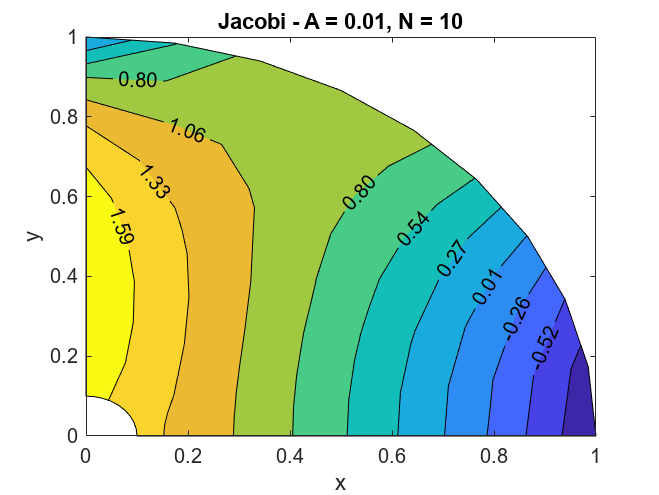

r100 =     0.1000    0.1091    0.1182    0.1273    0.1364    0.1455    0.1545    0.1636    0.1727    0.1818    0.1909    0.2000    0.2091    0.2182    0.2273    0.2364    0.2455    0.2545    0.2636    0.2727    0.2818    0.2909    0.3000    0.3091    0.3182    0.3273    0.3364    0.3455    0.3545    0.3636    0.3727    0.3818    0.3909    0.4000    0.4091    0.4182    0.4273    0.4364    0.4455    0.4545    0.4636    0.4727    0.4818    0.4909    0.5000    0.5091    0.5182    0.5273    0.5364    0.5455


matching_indices =      1     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     3     0     0     0     0     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     5     0     0     0     0     0


matching_indices =      1    12    23    34    45    56    78    89   100


Arrays have incompatible sizes for this operation.

Related documentation

clear; close all
% Parameters
a = 0.1;
R = 1;
th_final = pi/2;

ARange = [0, 1, 100];
NRange = [10, 20, 40];

for jj = [1:length(ARange)]
    for ii = [1:length(NRange)]
    
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %% Plotting
        A = ARange(jj);
        N = NRange(ii);
       
        % Ranges for independent variables
        r_range = linspace(a, R, N);
        th_range = linspace(0, th_final, N);
        r_mesh = repmat(r_range, N, 1);
        th_mesh = repmat(th_range', 1, N);
        x_coor = r_mesh .* cos(th_mesh);
        y_coor = r_mesh .* sin(th_mesh);
        filename = ['N' num2str(N) '_A' num2str(A) '.txt'];
        X_vector = readmatrix(filename);
        
        X_mesh = reshape(X_vector, [N, N]);
        X_mesh = -X_mesh';
        
        figure
        contourf(x_coor, y_coor, X_mesh, 10, "ShowText","on", "LabelFormat","%0.2f", "LabelSpacing",2000)
        hold on
        plot(zeros(N, 1), linspace(a, R, N), 'k')
        plot(linspace(a, R, N), zeros(N, 1), 'k')
        plot(a*cos(th_range), a*sin(th_range), 'k')
        plot(R*cos(th_range), R*sin(th_range), 'k')
        if A==0
            title_str = ['Jacobi - A = 0.01, N = ' num2str(N)];
            file_str = ['A91_N' num2str(N) '.png'];
        else
            title_str = ['Jacobi - A = ' num2str(A) ', N = ' num2str(N)];
            file_str = ['A' num2str(A) 'N' num2str(N) '.png'];
        end
        title(title_str)
        xlabel('x')
        ylabel('y')
        exportgraphics(gcf, file_str, 'Resolution', 300)

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %% RMS Error
        N100 = readmatrix(['..\iter' num2str(A)]);
        r100 = linspace(a, R, 100)
        [~, matching_indices] = ismember(r100, r_range)
        matching_indices = find(matching_indices)
        RMSError = rms(N100(matching_indices) - X_vector, 'all')
    end
end